## Load Dataset

data = readtable('plant_health_data.csv');
data.Properties.VariableNames

ans = 1×14 cell array
    {'Timestamp'}    {'Plant_ID'}    {'Soil_Moisture'}    {'Ambient_Temperature'}    {'Soil_Temperature'}    {'Humidity'}    {'Light_Intensity'}    {'Soil_pH'}    {'Nitrogen_Level'}    {'Phosphorus_Level'}    {'Potassium_Level'}    {'Chlorophyll_Content'}    {'Electrochemical_Signal'}    {'Plant_Health_Status'}


## Feature Engineering: Synthetic

if ~ismember('Stress_Score', data.Properties.VariableNames)
    fprintf('Creating synthetic Stress_Score based on soil moisture, temperature, and humidity.\n');
    normalizedMoisture = (data.Soil_Moisture - min(data.Soil_Moisture)) ./ (max(data.Soil_Moisture)-min(data.Soil_Moisture)+eps);
    normalizedTemp     = (data.Ambient_Temperature - min(data.Ambient_Temperature)) ./ (max(data.Ambient_Temperature)-min(data.Ambient_Temperature)+eps);
    normalizedHumidity = (data.Humidity - min(data.Humidity)) ./ (max(data.Humidity)-min(data.Humidity)+eps);
    data.Stress_Score = 0.5*(1-normalizedMoisture) + 0.3*normalizedTemp + 0.2*(1-normalizedHumidity);
end

Creating synthetic Stress_Score based on soil moisture, temperature, and humidity.


soilMoistureMean = mean(data.Soil_Moisture);
soilMoistureStd = std(data.Soil_Moisture);
tempMean = mean(data.Soil_Temperature);
tempStd = std(data.Soil_Temperature);
phMean = mean(data.Soil_pH);
phStd = std(data.Soil_pH);
data.AnomalyDetected = double( ...
    abs(data.Soil_Moisture - soilMoistureMean) > 2*soilMoistureStd | ...
    abs(data.Soil_Temperature - tempMean) > 2*tempStd | ...
    abs(data.Soil_pH - phMean) > 2*phStd );
data.LeafWetness = double(data.Humidity > 60 | data.Ambient_Temperature < 20)

data = 1200×17 table
           Timestamp           Plant_ID    Soil_Moisture    Ambient_Temperature    Soil_Temperature    Humidity    Light_Intensity    Soil_pH    Nitrogen_Level    Phosphorus_Level    Potassium_Level    Chlorophyll_Content    Electrochemical_Signal    Plant_Health_Status    Stress_Score    AnomalyDetected    LeafWetness
    _______________________    ________    _____________    ___________________    ________________    ________    _______________    _______    ______________    ________________    ________

humidityNorm = data.Humidity / 100;         
tempNorm = (data.Ambient_Temperature - 20) / 20; 
tempNorm(tempNorm<0) = 0; tempNorm(tempNorm>1) = 1;

leafWetnessNorm = data.LeafWetness;         

data.PestRiskScore = 0.5*humidityNorm + 0.3*tempNorm + 0.2*leafWetnessNorm;

data.PestRiskScore(data.PestRiskScore>1) = 1;
data.PestRiskScore(data.PestRiskScore<0) = 0;

## LSTM input features and Targets

inputFeatures = { ...
    'Soil_Moisture', ...
    'Ambient_Temperature', ...
    'Soil_Temperature', ...
    'Humidity', ...
    'Light_Intensity', ...
    'Soil_pH', ...
    'Nitrogen_Level', ...
    'Phosphorus_Level', ...
    'Potassium_Level', ...
    'Chlorophyll_Content', ...
    'Electrochemical_Signal', ...
    'LeafWetness' ...
};

targetVars = { ...
    'Soil_Moisture', ...           
    'Ambient_Temperature', ...    
    'Humidity', ...                
    'Soil_Temperature', ...        
    'Chlorophyll_Content', ...     
    'Stress_Score', ...            
    'AnomalyDetected', ...        
    'Plant_Health_Status', ...   
    'PestRiskScore' ...
    };

## Normalising Inputs and Targets

X_all = data{:,inputFeatures};
minX = min(X_all); maxX = max(X_all);
X_norm_all = (X_all - minX) ./ (maxX - minX + eps);

Y_all = zeros(height(data), length(targetVars));

for i = 1:length(targetVars)
    col = data.(targetVars{i});
    
    % Convert categorical or cell to numeric labels
    if iscell(col) || iscategorical(col)
        col = double(categorical(col));
    end
    
    Y_all(:,i) = col;
end

% Normalize Y_all if needed
minY = min(Y_all); maxY = max(Y_all);
Y_norm_all = (Y_all - minY) ./ (maxY - minY + eps);

## Preparing Sequence

seqLength = 30;      % number of past timesteps
predDays   = 7;      % prediction window

numRows    = height(data);
numSamples = numRows - seqLength - predDays + 1;

% Initialize cell arrays
X_seq           = cell(1,numSamples);  
Y_seq           = cell(1,numSamples); 
Y_health_seq    = cell(1,numSamples); 

% Convert Plant_Health_Status to numeric labels
healthNumeric = double(categorical(data.Plant_Health_Status));

for i = 1:numSamples
    X_seq{i} = X_norm_all(i:i+seqLength-1,:)';
    
    futureNorm = Y_norm_all(i+seqLength:i+seqLength+predDays-1,:);
    Y_seq{i} = futureNorm(:)'; 
    
    futureHealth = healthNumeric(i+seqLength:i+seqLength+predDays-1);
    Y_health_seq{i} = mode(futureHealth);
end

% Optional: convert Y_health_seq to categorical for classification LSTM
Y_health_seq_cat = cellfun(@(x) categorical(x), Y_health_seq, 'UniformOutput', false);

disp('Sequences prepared for regression and classification LSTM!');

Sequences prepared for regression and classification LSTM!



%% Remove sequences with NaNs
valid = true(1,numSamples);
for i=1:numSamples
    if any(isnan(X_seq{i}(:))) || any(isnan(Y_seq{i}(:)))
        valid(i) = false;
    end
end
X_seq = X_seq(valid);
Y_seq = Y_seq(valid);
Y_health_seq = Y_health_seq(valid);
numSamplesClean = numel(X_seq);
fprintf('Usable sequences after NaN-cleaning: %d\n', numSamplesClean);

Usable sequences after NaN-cleaning: 1164



%% Train-Test Split
idxTrain = floor(0.8*numSamplesClean);
XTrain = X_seq(1:idxTrain); XTest  = X_seq(idxTrain+1:end);

YTrain_reg_cells = Y_seq(1:idxTrain);
YTest_reg_cells  = Y_seq(idxTrain+1:end);

YTrain_class = categorical([Y_health_seq{1:idxTrain}]);
YTest_class  = categorical([Y_health_seq{idxTrain+1:end}]);

YTrain_reg_mat = vertcat(YTrain_reg_cells{:});
YTest_reg_mat  = vertcat(YTest_reg_cells{:});
fprintf('Train samples: %d | Test samples: %d | Regression target dim: %d\n', numel(XTrain), numel(XTest), size(YTrain_reg_mat,2));

Train samples: 931 | Test samples: 233 | Regression target dim: 63


## Regression Model

%% LSTM Regression Model
numFeatures  = size(XTrain{1},1);
numResponses = size(YTrain_reg_mat,2);

layers_reg = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(128,'OutputMode','last')
    fullyConnectedLayer(numResponses)
    regressionLayer];

options_reg = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'MiniBatchSize',32, ...
    'Shuffle','every-epoch', ...
    'Plots','none', ...
    'Verbose',0, ...
    'ValidationData',{XTest,YTest_reg_mat});

regressionNet = trainNetwork(XTrain,YTrain_reg_mat,layers_reg,options_reg);

## Classification Model

%% LSTM Classification Model
numClasses = numel(categories(YTrain_class));
layers_class = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(128,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

options_class = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'MiniBatchSize',32, ...
    'Shuffle','every-epoch', ...
    'Plots','none', ...
    'Verbose',0, ...
    'ValidationData',{XTest,YTest_class});

classificationNet = trainNetwork(XTrain,YTrain_class,layers_class,options_class);

## Evaluation

%% Evaluate Test Predictions (regression & classification)
YPred_reg_norm = predict(regressionNet,XTest);   
YPred_class = classify(classificationNet,XTest);

% single-line summary metrics
trainAcc = mean(classify(classificationNet,XTrain) == YTrain_class);
valAcc   = mean(YPred_class == YTest_class);


## Denormalization

%% Denormalize predictions & ground truth for regression
numTest = numel(XTest);
numTargets = numel(targetVars);

YTest_reg_mat_denorm = zeros(size(YTest_reg_mat));
YPred_reg_denorm = zeros(size(YPred_reg_norm));

for i=1:size(YTest_reg_mat,1)
    yTrue_norm = YTest_reg_mat(i,:);
    yPred_norm = YPred_reg_norm(i,:);
    % convert back sample-wise
    yTrueMat = reshape(yTrue_norm, [predDays, numTargets]);
    yPredMat = reshape(yPred_norm, [predDays, numTargets]);
    yTrueOrig = yTrueMat .* (maxY - minY) + minY;
    yPredOrig = yPredMat .* (maxY - minY) + minY;
    YTest_reg_mat_denorm(i,:) = yTrueOrig(:)';
    YPred_reg_denorm(i,:) = yPredOrig(:)';
end

## RMSE

%% Compute per-target RMSE (aggregated across all days & samples)
rmsePerTarget = zeros(1,numTargets);
for t=1:numTargets
    idx = (t-1)*predDays + (1:predDays);
    errors = YTest_reg_mat_denorm(:,idx) - YPred_reg_denorm(:,idx);
    rmsePerTarget(t) = sqrt(mean(errors(:).^2));
end

% Print RMSEs
fprintf('Regression RMSE per target:\n');

Regression RMSE per target:


for t=1:numTargets
    fprintf('  %s: %.4f\n', targetVars{t}, rmsePerTarget(t));
end

  Soil_Moisture: 8.8552
  Ambient_Temperature: 3.5620
  Humidity: 9.0482
  Soil_Temperature: 2.9740
  Chlorophyll_Content: 8.8124
  Stress_Score: 0.1843
  AnomalyDetected: 0.0000
  Plant_Health_Status: 0.7447
  PestRiskScore: 0.1371


## Visuals

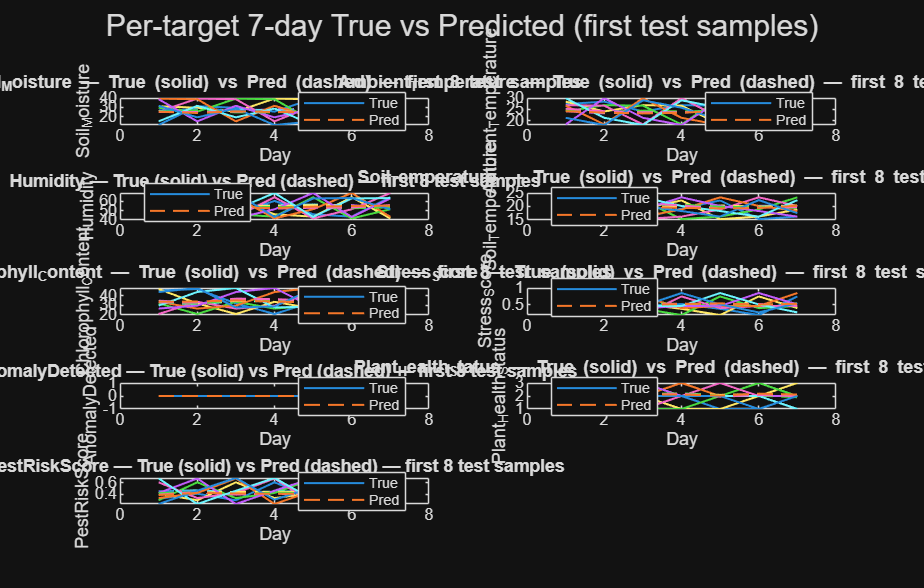

%% Visuals: Per-target true vs predicted for the first N test samples (stacked)
Nplot = min(8, numTest);
figure('Position',[100 100 1100 700]);
for t = 1:numTargets
    subplot(ceil(numTargets/2),2,t);
    hold on; box on;
    for i=1:Nplot
        idx = (t-1)*predDays + (1:predDays);
        plot(1:predDays, YTest_reg_mat_denorm(i,idx), 'LineWidth', 1); % true
        plot(1:predDays, YPred_reg_denorm(i,idx), '--', 'LineWidth', 1); % pred
    end
    xlabel('Day'); ylabel(targetVars{t});
    title(sprintf('%s — True (solid) vs Pred (dashed) — first %d test samples', targetVars{t}, Nplot));
    legend({'True','Pred'}, 'Location','best');
    hold off;
end
sgtitle('Per-target 7-day True vs Predicted (first test samples)');
exportgraphics(gcf,'regression_true_vs_pred_samples.pdf','ContentType','vector');

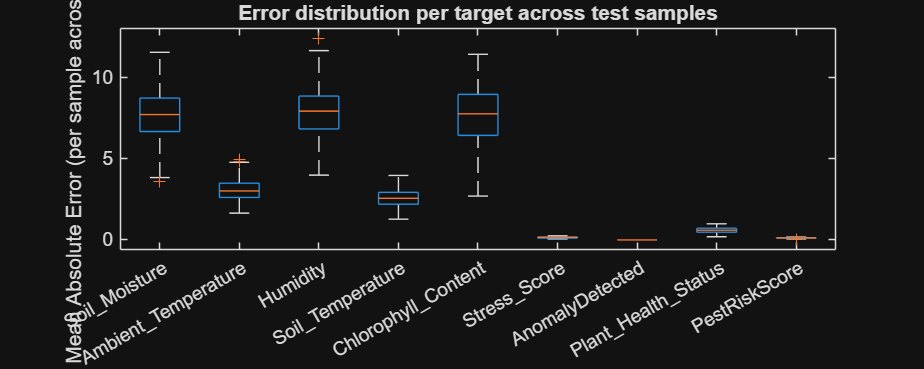


%% Plot aggregated error box per target (for each day)
figure('Position',[100 100 1000 400]);
errMatrix = zeros(numTest, numTargets);
for t=1:numTargets
    idx = (t-1)*predDays + (1:predDays);
    errMatrix(:,t) = mean(abs(YTest_reg_mat_denorm(:,idx) - YPred_reg_denorm(:,idx)), 2); % per-sample avg abs error for target
end
boxplot(errMatrix, 'Labels', targetVars);
ylabel('Mean Absolute Error (per sample across 7 days)');
title('Error distribution per target across test samples');
exportgraphics(gcf,'regression_error_boxplot.pdf','ContentType','vector');

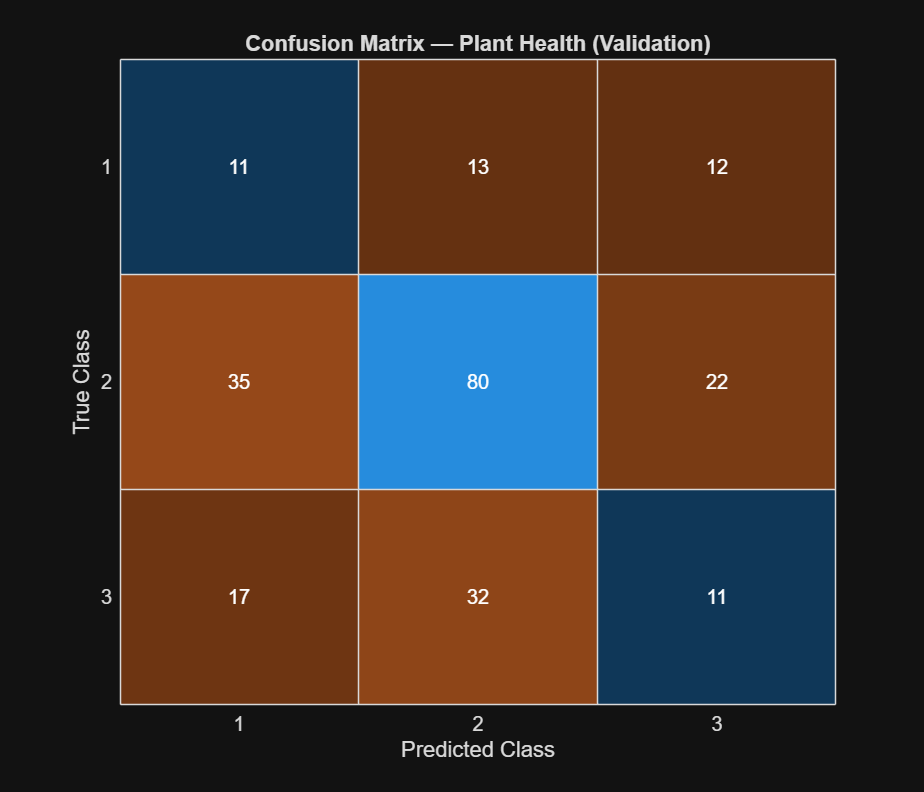

%% Classification: Confusion Matrix & metrics
figure('Position',[100 100 700 600]);
confusionchart(YTest_class, YPred_class);
title('Confusion Matrix — Plant Health (Validation)'); 
exportgraphics(gcf,'confusion_matrix.pdf','ContentType','vector');

## Preparing a Forecast Table for Test Data

%% Build full forecast table for test set (denormalized, clean)
predDays = 7;  

% Only regression targets
regressionTargets = { ...
    'Soil_Moisture', ...
    'Ambient_Temperature', ...
    'Humidity', ...
    'Soil_Temperature', ...
    'Chlorophyll_Content', ...
    'Stress_Score', ...
    'AnomalyDetected', ...
    'PestRiskScore' ...
    };

numRegressionTargets = numel(regressionTargets);

% Build proper column names
colNames = strings(1, numRegressionTargets*predDays);
for t = 1:numRegressionTargets
    for d = 1:predDays
        colNames((t-1)*predDays + d) = regressionTargets{t} + "_Day" + string(d);
    end
end

% Add final categorical column name
colNames = [colNames, "Predicted_Plant_Health"];

fullTableData = zeros(numTest, numRegressionTargets*predDays);
for i = 1:numTest
    fullTableData(i,:) = YPred_reg_denorm(i, 1:(numRegressionTargets*predDays));
end


fullTable = array2table(fullTableData, 'VariableNames', cellstr(colNames(1:end-1)));


fullTable.Predicted_Plant_Health = string(YPred_class);

% Save to CSV
writetable(fullTable,'7Days_Forecast_TestSamples.csv');
fprintf('Test forecast table saved as clean CSV with categorical health labels.\n');

Test forecast table saved as clean CSV with categorical health labels.


## User Input Section

inputFeatures = { ...
    'Soil_Moisture', ...
    'Ambient_Temperature', ...
    'Soil_Temperature', ...
    'Humidity', ...
    'Light_Intensity', ...
    'Soil_pH', ...
    'Nitrogen_Level', ...
    'Phosphorus_Level', ...
    'Potassium_Level', ...
    'Chlorophyll_Content', ...
    'Electrochemical_Signal', ...
    'LeafWetness' ...
};

targetVars = { ...
    'Soil_Moisture', ...
    'Ambient_Temperature', ...
    'Humidity', ...
    'Soil_Temperature', ...
    'Chlorophyll_Content', ...
    'Stress_Score', ...
    'AnomalyDetected', ...
    'Plant_Health_Status', ...
    'PestRiskScore' ...
};

numFeatures = numel(inputFeatures);
numTargets = numel(targetVars);
predDays = 7;


userInput = zeros(1, numFeatures);
fprintf('Please provide current values for the following features:\n');

Please provide current values for the following features:


for i = 1:numFeatures
    prompt = sprintf('%s: ', inputFeatures{i});
    userInput(i) = input(prompt);
end


minX = min(X_all); maxX = max(X_all);
userInput_norm = (userInput - minX) ./ (maxX - minX + eps);


X = userInput_norm';
X = {X};

YPred_reg_norm = predict(regressionNet, X);
YPred_reg_norm = reshape(YPred_reg_norm, [], size(maxY,2));   % (63 × 9)


YPred_reg_denorm = YPred_reg_norm .* (maxY - minY) + minY;

YPred_class = classify(classificationNet, X);

healthLabels = categories(YTrain_class);  % use same labels as training
predictedHealth = string(YPred_class);

fprintf('\n--- 7-Day Forecast ---\n');


--- 7-Day Forecast ---


for t = 1:numTargets
    if strcmp(targetVars{t}, 'Plant_Health_Status')
        fprintf('%s: %s\n', targetVars{t}, predictedHealth);
    else
        fprintf('%s: ', targetVars{t});
        fprintf('%.2f ', YPred_reg_denorm(1:predDays, t));  
        fprintf('\n');
    end
end

Soil_Moisture: 

12.72 12.78 11.93 12.87 12.48 15.11 12.53 

Ambient_Temperature: 

18.88 18.68 19.65 19.13 19.02 18.21 18.68 

Humidity: 

44.08 42.78 42.33 44.79 45.00 42.43 41.38 

Soil_Temperature: 

16.52 16.57 16.03 17.03 16.85 15.66 15.26 

Chlorophyll_Content: 

21.02 19.32 23.82 22.69 23.49 23.71 25.00 

Stress_Score: 

0.16 0.16 0.21 0.14 0.17 0.14 0.17 

AnomalyDetected: 

0.00 0.00 0.00 0.00 0.00 0.00 0.00 

Plant_Health_Status: 2


PestRiskScore: 

0.25 0.27 0.26 0.28 0.29 0.23 0.23 